# Contextual View Widget

*Copyright 2025 The MathWorks, Inc.*

The [`wt.ContextualView`](matlab:open('..\+wt\ContextualView.m')) widget is an advanced component intended for use in apps with a modular implementation using the [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller) (MVC) design pattern. The `ContextualView` provides a multiple-view container for recangular contents similar to a `uitabgroup. However`, unliike `uitabgroup`, the `ContextualView` provides only a programmatic interface for launching a component and placing it within the widget. 

## Example

In this example, the `ContextualView` is shown with multiple different views and models. 

### Create the component

First, create a figure and grid layout:

fig1 = uifigure("Position",[100 100 300 250]);

grid1 = uigridlayout(fig1,[1 1]);
grid1.BackgroundColor = [.2 0 0]; % Color the grid dark red

Then add the `ContextualView` component:

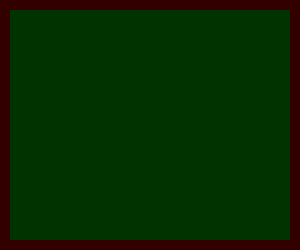

cview = wt.ContextualView(grid1);
cview.BackgroundColor = [0 .2 0]; % Color the ContextualView dark green

Note that background colors have been adjusted from defaults to clearly show the component's placement within the grid. The `ContextualView` component is initially empty green until a view is launched.

### Create model classes to show

We need to create some data to show in the views that we will launch. Following from the [Zoo Hierarchy App Example](matlab:open('./AdvancedAppZooHierarchyExample.mlx')), we create model class instances for two animals that reside within a zoo enclosure:

First animal:

animalModel1 = wt.example.model.Animal;
animalModel1.Species = "Lion";
animalModel1.Name = "Simba";
animalModel1.Sex = "male";
animalModel1.BirthDate = "March 9, 1994";

Second animal:

animalModel2 = wt.example.model.Animal;
animalModel2.Species = "Lion";
animalModel2.Name = "Nala";
animalModel2.Sex = "female";
animalModel2.BirthDate = "September 13, 1994";

An enclosure where the animals live:

enclosureModelA = wt.example.model.Enclosure;
enclosureModelA.Name = "Lions' Den";
enclosureModelA.Animal = [animalModel1; animalModel2]; % Links them to this enclosure

### Display an Enclosure view

Next, we can launch a view to be placed within the `ContextualView`. This is done using the `launchView` method. 

We provide additional inputs to indicate what to launch and display:

- The full class name of the view to launch

- The model to display within the view

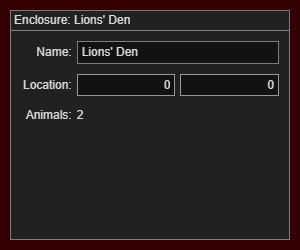

cview.launchView("wt.example.view.Enclosure", enclosureModelA);

This results in the view [`wt.example.view.Enclosure`](matlab:open('./+wt\+example\+view\Enclosure.m')) being displayed, showing the data for the model that is an instance of [`wt.example.model.Enclosure`](matlab:open('./+wt\+example\+model\Enclosure.m')). 

### Display an Animal view

We can switch the contents of the `ContextualView` by simply launching a different view. To do this, we now launch the view [`wt.example.view.Animal`](matlab:open('./+wt\+example\+view\Animal.m')) with a model of class [`wt.example.model.Animal`](matlab:open('./+wt\+example\+model\Animal.m')).

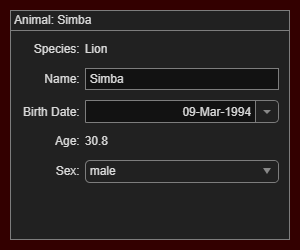

cview.launchView("wt.example.view.Animal", animalModel1);

The first time a view is launched into a `ContextualView` may take longer than subsequent times, because the `ContextualView` retains and reuses previous view types for optimal performance. When we switched away from the `Enclosure` view, it was simply hidden and the model detached. However, the deactivated view is kept in memory of the `ContextualView` widget for a faster launch next time.

### Display a different Animal in the view

If we want to reuse the same Animal view but display a different model in the `ContextualView`, use the same launchView method. 

Here we switch to the second animal model:

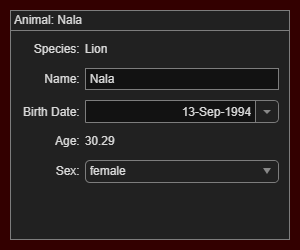

cview.launchView("wt.example.view.Animal", animalModel2);

In this case, the view class stays the same but the model instance changed. The `ContextualView` is optimized to simply attach the new model to the existing view.

## Developing View Class Components for ContextualView

The [`wt.ContextualView`](matlab:open('..\+wt\ContextualView.m')) requires its views to inherit from [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) or [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')), and the concrete class for the view (e.g. `Animal`, `Enclosure`) must implement a `Model` property. The class inheritance diagram is shown below:

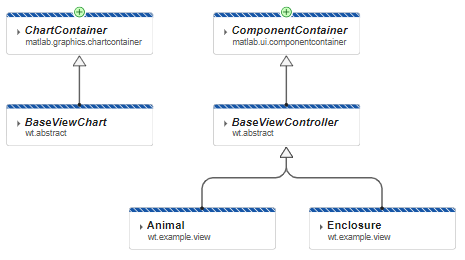

The example `Animal` and `Enclosure` classes previously shown are subclasses of `BaseViewController`. Determine which superclass to use based on the intended contents:

- The class  [`wt.abstract.BaseViewChart`](matlab:open('..\+wt\+abstract\BaseViewChart.m')) may be used when the view/controller to be placed in the `ContextualView` contains only axes and can be implemented as a [ChartContainer](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chartcontainer.chartcontainer-class.html) subclass.

- The class  [`wt.abstract.BaseViewController`](matlab:open('..\+wt\+abstract\BaseViewController.m')) must be used when the view/controller to be placed in the `ContextualView` contains any combination of axes and app components and will be implemented as a [ComponentContainer](https://www.mathworks.com/help/matlab/ref/matlab.ui.componentcontainer.componentcontainer-class.html) subclass.

## Public Interface

The public interface to the `ContextualView` is described below:

### Properties

#### BlockWhileLoading

When set to `TRUE`, the contents of `ContextualView` will be blocked from user interactions while the contents are being changed.

#### LoadingImageSource

Defines the image file that will be shown while a view is loading. This applies only when BlockWhileLoading is set to `TRUE.`

#### ActiveView (read-only)

The actively loaded view's class object. 

#### LoadedViews (read-only)

An array of all views that have been loaded into `ContextualView` that are either active or stored for faster launch.

### Methods

#### launchView

`activeView = launchView(obj, viewClass, model)`

This method launches a view of the specified class name with the given model. Optionally return the view object as an output argument. The activeView will also be stored in the `ActiveView` property.

#### prepareToLaunchView

`prepareToLaunchView(objArray, viewClassArray)`

This is an optional method that will set multiple instances of `ContextualView` in a "loading" state just prior to calling `launchView`. Use this if you have multiple `ContextualView` widgets in your app (`objArray)` that must update simultaneously to the new view class names (`viewClassArray) `and you want them to appear synchronized in a loading state when preparing to launch different views. 

#### clearView

`clearView(obj)`

This method deactivates the currently active view, leaving `ContextualView` to appear empty of any view. Previously launched views are still kept ready under the `LoadedViews` property.

#### relaunchActiveView (for debugging)

`relaunchActiveView(obj)`

This method is useful for debugging. It deletes and relaunches the active view (instead of reusing it). This is often needed when actively developing the view being placed inside `ContextualView` and you want it to be reloaded to show the latest code changes.

#### reset (for debugging)

`reset(obj)`

This method is useful for debugging. It deletes all views loaded into the `ContextualView` to reset it to initial state. 

## Deployment Considerations

When packaging an app using MATLAB Compiler, the view/controller classes utilized by `ContextualView` (and any of their dependencies) may not automatically be included. This is because the views are launched by the class name as a string (e.g. `"wt.example.view.Enclosure"`), so the dependency analysis would not be able to detect the `wt.example.view.Enclosure` dependency. For a successful deployment, you should manually include the source code folder(s) containing the views and any downstream dependencies.

## References

- Documentation: [Advanced Application Development: Using Model-View-Controller Architecture](matlab:open('./UsingModelViewControllerClasses.mlx'))

- App Example: [Zoo Hierarchy App Example](matlab:open('./AdvancedAppZooHierarchyExample.mlx'))

- Article: [Developing MATLAB Apps Using the Model-View-Controller Pattern - MATLAB & Simulink](https://www.mathworks.com/company/technical-articles/developing-matlab-apps-using-the-model-view-controller-pattern.html)

- Webinar: [Application Development Strategies in MATLAB - MATLAB](https://www.mathworks.com/videos/application-development-strategies-in-matlab-1689014110815.html)

- Training: [Advanced MATLAB Application Development - MATLAB & Simulink](https://www.mathworks.com/learn/training/advanced-matlab-application-development.html)

- Reference: [model-view-controller](https://en.wikipedia.org/wiki/Model%E2%80%93view%E2%80%93controller)